# shade

Filled area 2-D line plot

### Syntax

`shade` uses the same syntax as `plot`. Any valid `plot` calls are also valid `shade` calls.

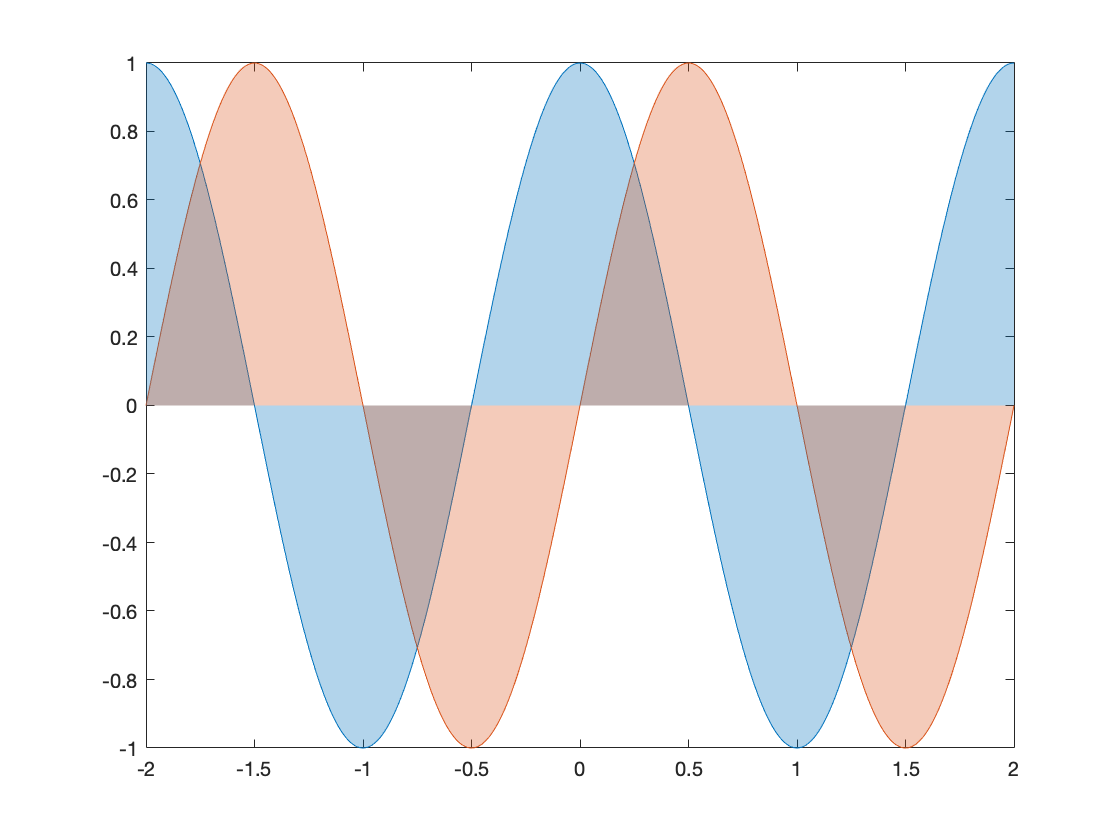

x = -2:0.01:2;
y1 = cos(pi*x);
y2 = sin(pi*x);

shade(x,y1,x,y2)

`shade` draws the lines in the same way as `plot` but also fills the area under the curve.

### General Plot Options

Specify any plot options as you would for `plot`. You can use line specifiers and name-value pair arguments.

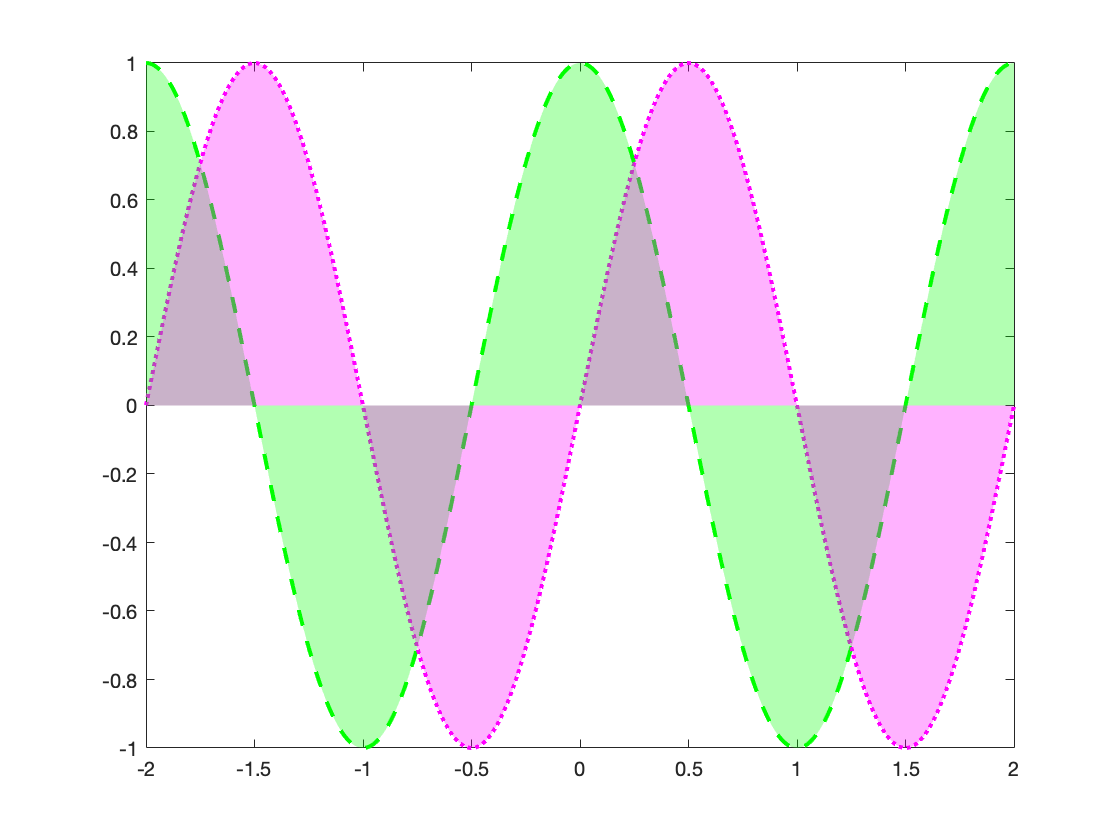

shade(x,y1,'--g',x,y2,':m','LineWidth',2)

You may also specify the axes object on which the plot should be created.

### **Fill**ing Options

#### Fill Type

The parameter `FillType` may be used to specify which areas should be filled. This should be a two-column matrix, where the left and right columns of each row are indices specifying the upper and lower bounds of a filled area.

To fill the area between lines 1 and 2, where line 1 is the upper bound and line 2 is the lower bound, specify:

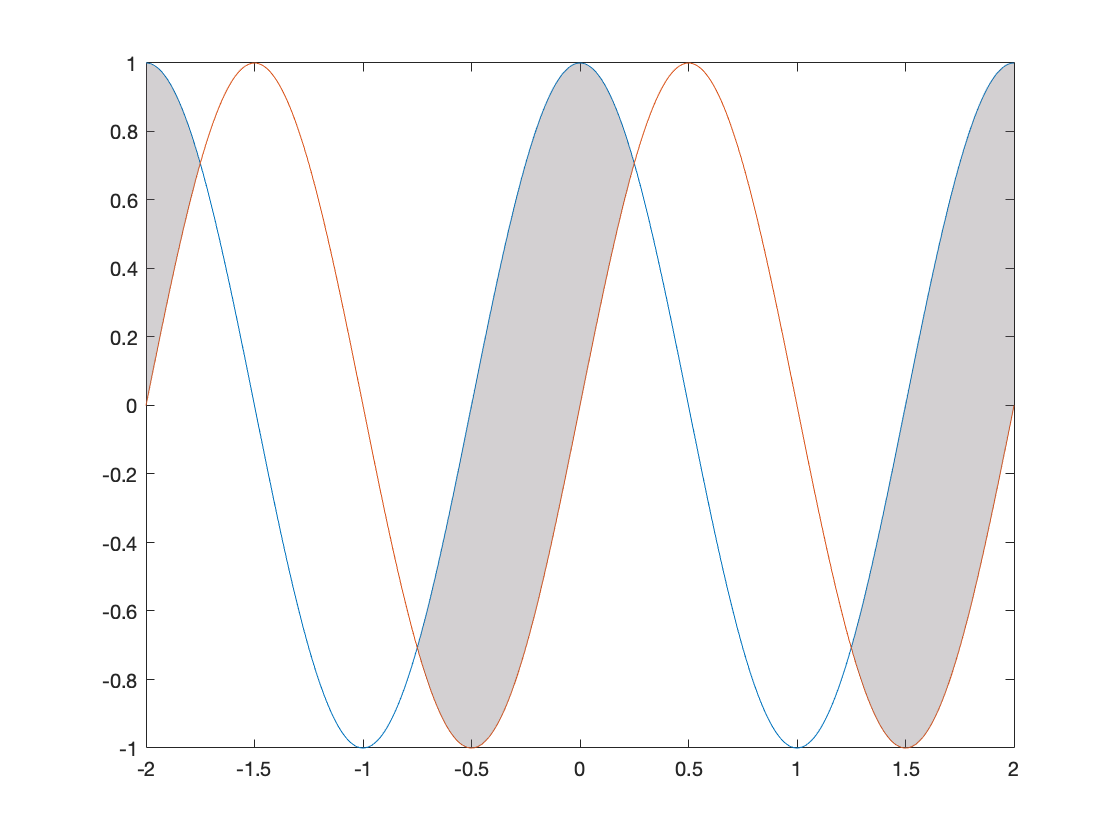

shade(x,y1,x,y2,'FillType',[1 2])

More than one row can be specified to fill more than one area. To also fill those parts where curve 2 is above curve 1, use:

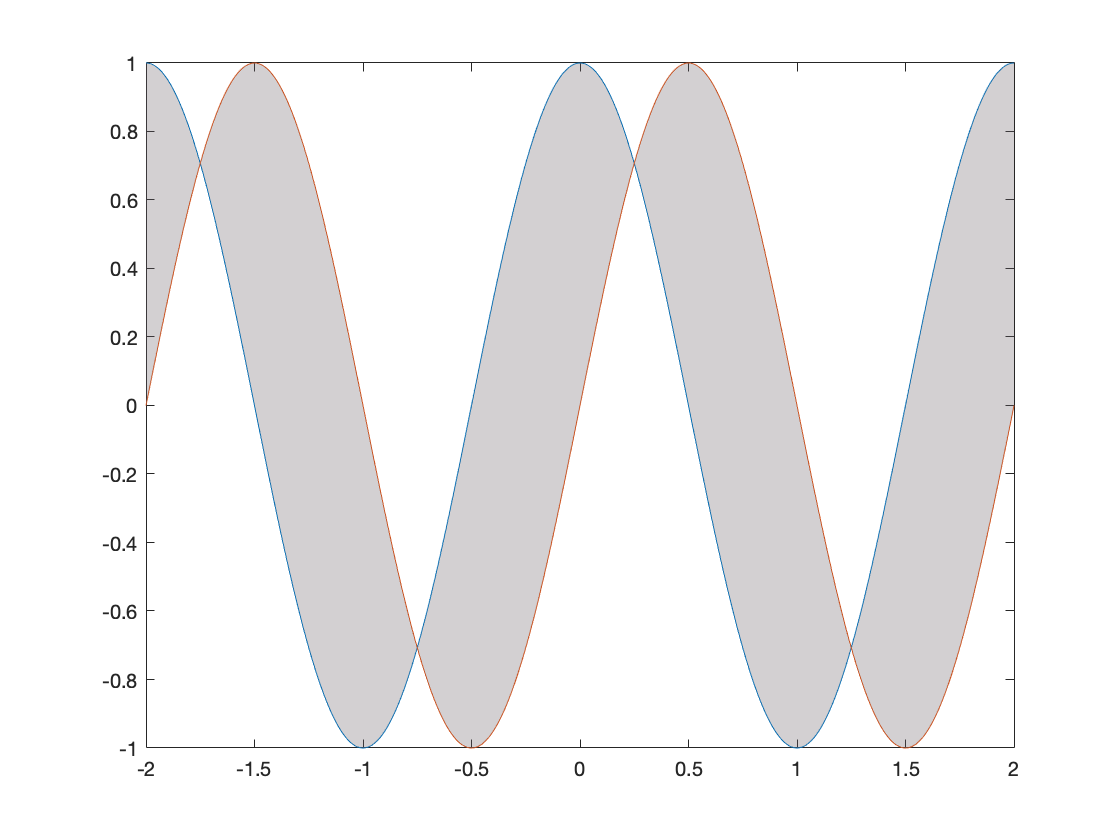

shade(x,y1,x,y2,'FillType',[1 2;2 1])

The value 0 represents the *x*-axis. Fill to the *x*-axis, only for curve 1:

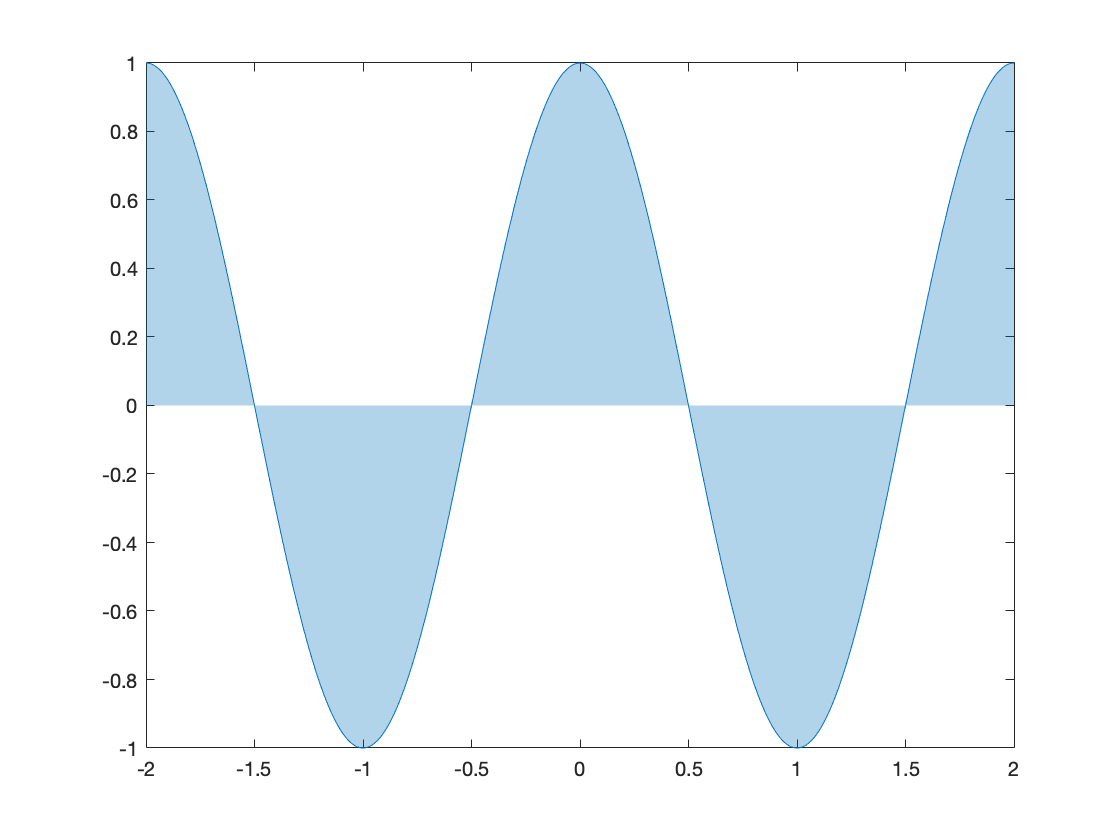

shade(x,y1,'FillType',[1 0;0 1])

A cell array may also be used to specify the fill type. In this case, one can use the keywords `axis`, `bottom` and `top` in addition to indices. To fill to the bottom of the active axes, use:

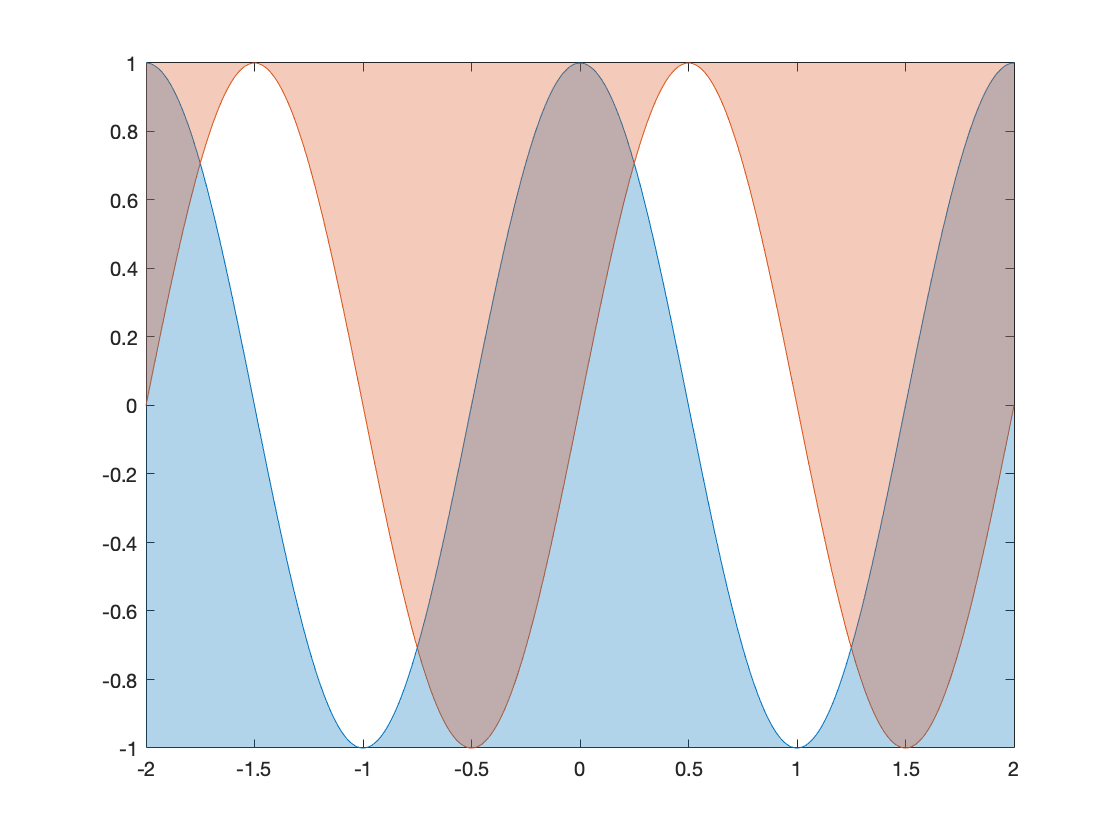

shade(x,y1,x,y2,'FillType',{1 'bottom';'top' 2})

Note that `bottom` can only be used on the second column, while `top` can only be used on the first.

#### Fill Color

By changing line colors using the tools made available by `plot`, the fill color will automatically adapt accordingly to reflect the color of the corresponding line.

However, the fill color can also be changed independently using the parameter `FillColor`. This should be a three-column matrix with the same number of rows as `FillType`, where each row is an RGB triplet (if `FillType` was not manually specified, it has 2*N rows, where N is the number of lines in the plot).

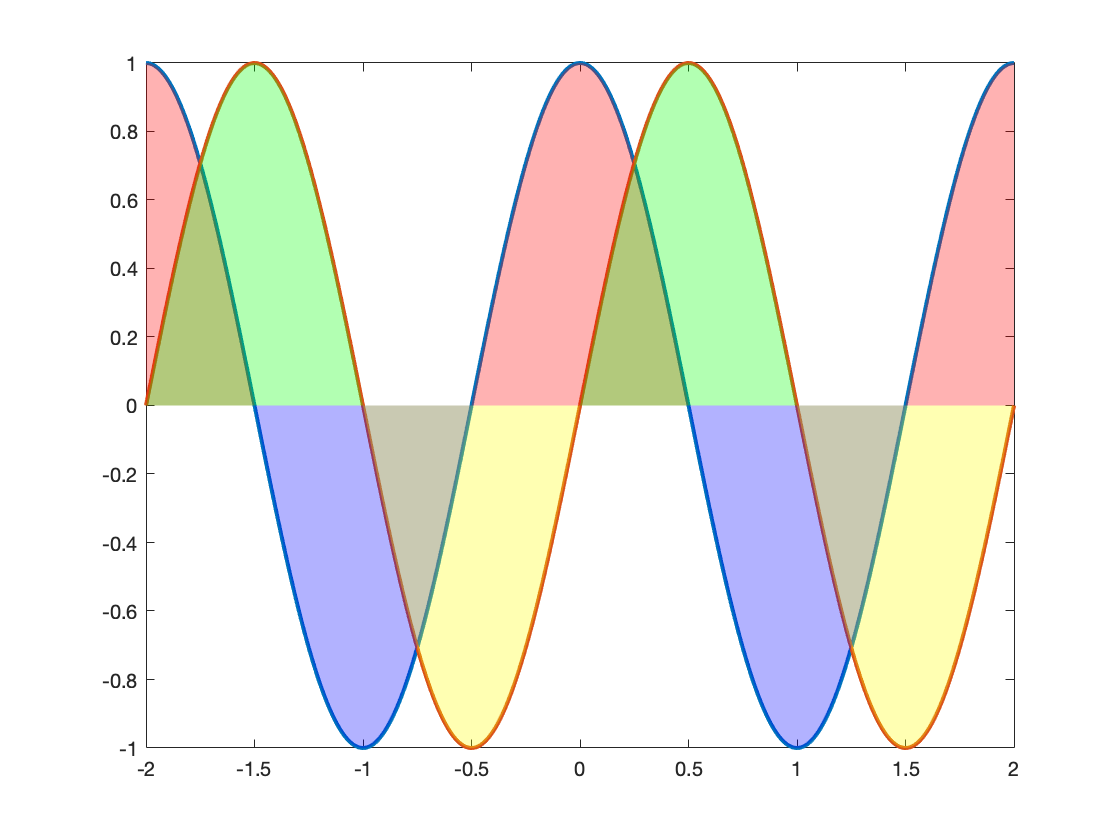

shade(x,y1,x,y2,'LineWidth',2,'FillColor',[1 0 0;0 0 1;0 1 0;1 1 0])

If only one RGB triplet is specified, the same color is used for all areas:

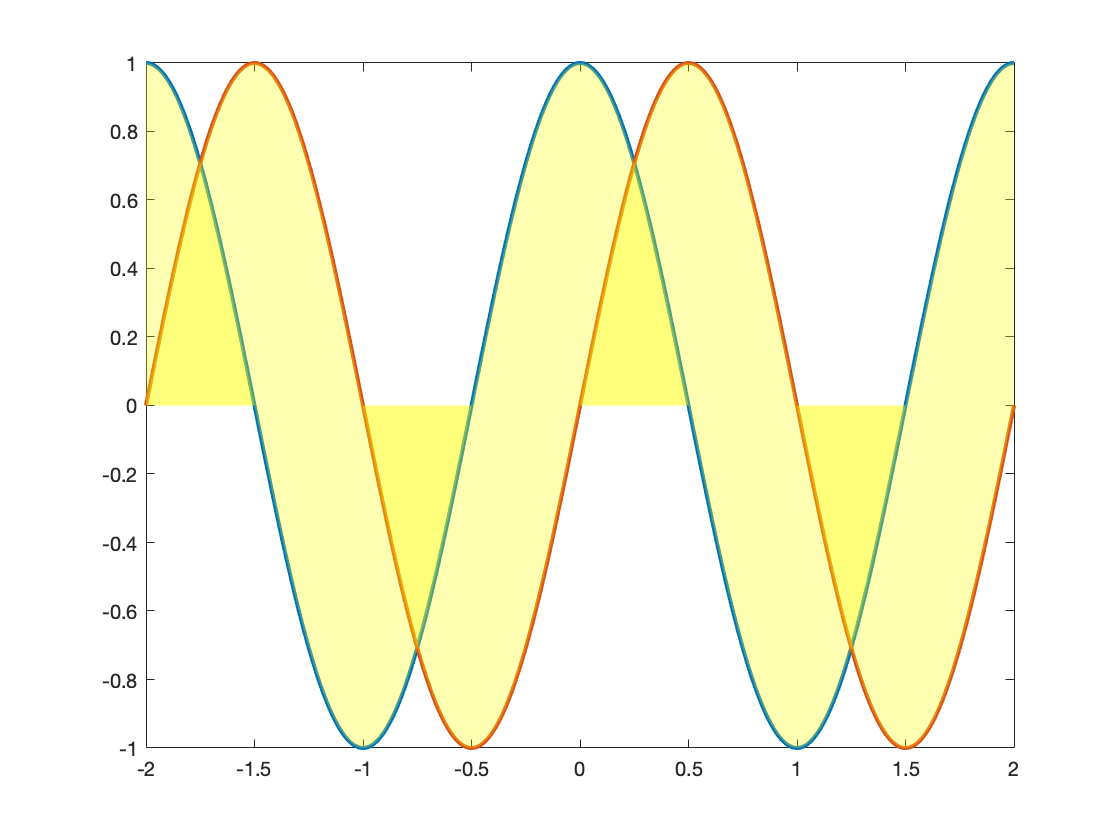

shade(x,y1,x,y2,'LineWidth',2,'FillColor',[1 1 0])

`FillColor` may also be specified using a cell array, in which case color names can also be used as specifiers. A cell array should have as many entries as rows in the `FillType` matrix or cell array, or only one entry in which case the same color is used for all areas. Color names and RGB triplets may be combined in a cell array.

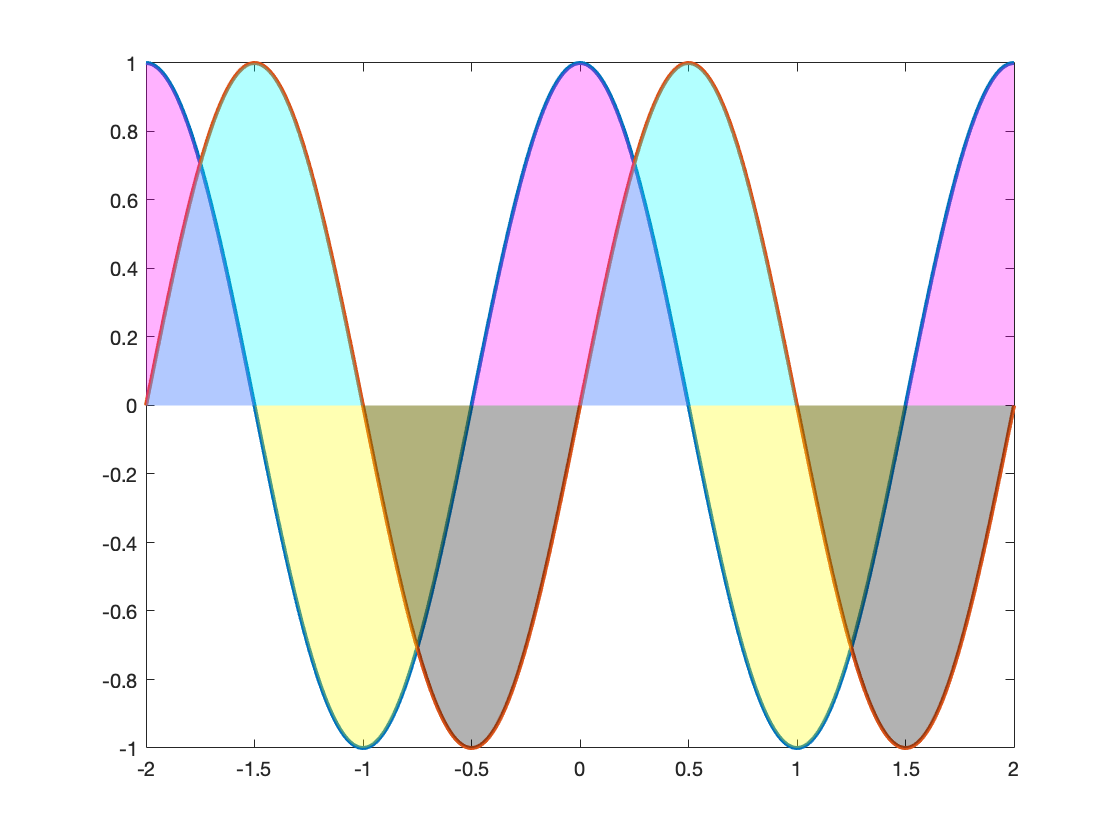

shade(x,y1,x,y2,'LineWidth',2,'FillColor',{'magenta','yellow','cyan','black'})

#### Fill Alpha

`FillAlpha` may be specified to change the transparency properties of the filled areas. This should be a vector with as many entries as rows in the `FillType` matrix or cell array. Alternatively, if only one value is specified, the same alpha is used for all areas.

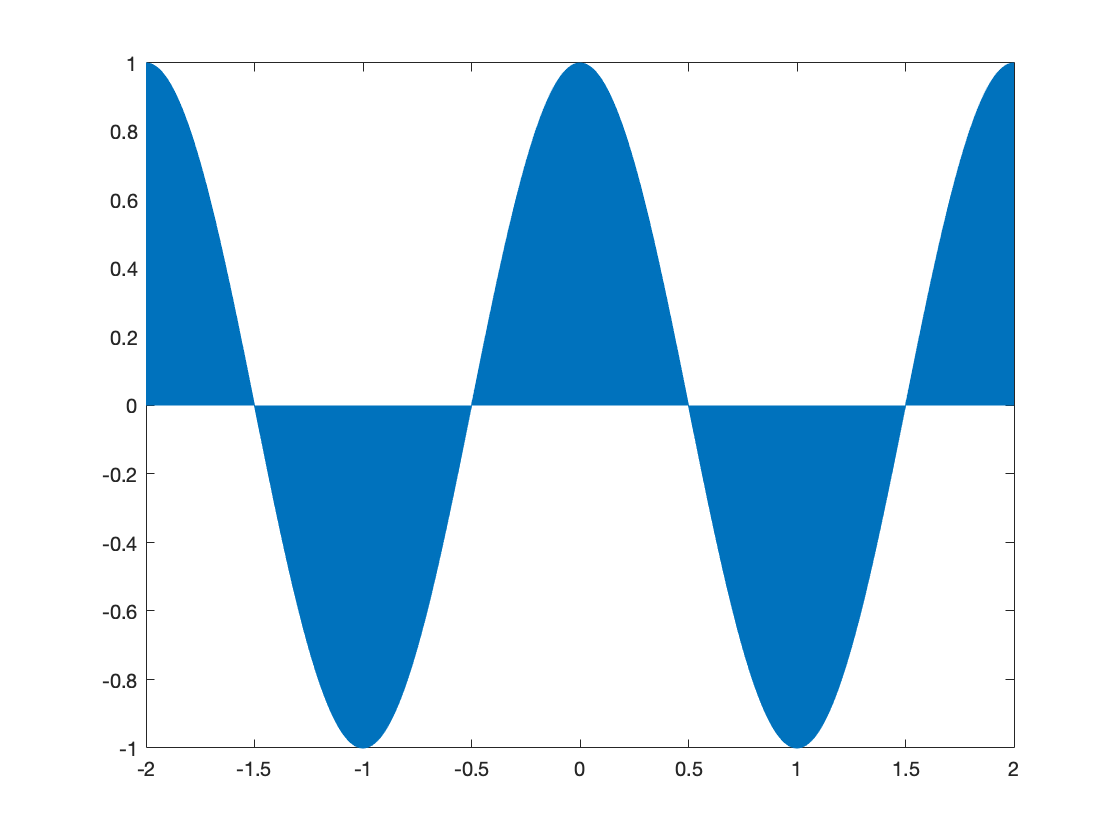

shade(x,y1,'FillAlpha',1)

### Outputs

Specify an output argument to get an array of handles to all plot objects, including lines and filled areas. You may use these handles to modify graphics properties after creation.

h =   6×1 graphics array:

  Line
  Line
  Patch
  Patch
  Patch
  Patch


h = shade(x,y1,x,y2)